# **TRA445 Advanced battery modelling and control **

### **Tutorial on physics-based modelling**

### **Yicun Huang **

#### Introduction

In this tutorial, we will develop a simple physics-based model for lithium-ion batteries known as the Single Particle Model (SPM). The SPM is an electrochemical model that captures the essential physics of lithium-ion batteries, including ion transport and reaction kinetics. This model can be coupled with other models, such as bulk thermal models or aging mechanisms, to provide a comprehensive understanding of battery behavior.

The SPM is an approximation to the more complex pseudo-two-dimensional (P2D) lithium-ion battery model. In the SPM, the porous active material of each electrode (anode and cathode) is represented by a single spherical particle of active material. The parameters of these particles are chosen to approximate the properties of the electrodes' material. This simplification allows us to focus on the solid-phase transport of lithium within the electrode particles while neglecting the electrolyte transport limitations that are only present at high C-rates. As a result, the SPM is valid for low current rates, typically up to 1C or sometimes 2C, depending on the battery design.

#### Assumptions

Compared to the P2D model, the SPM makes several key assumptions:

- **Single Particle Representation**: Each electrode (anode and cathode) is represented by a single spherical particle, approximating the porous structure of the electrode material.

- **Neglected Electrolyte Transport**: The SPM assumes that the transport of lithium in the electrolyte is fast compared to solid-phase transport, thus neglecting electrolyte diffusion and migration.

- **Uniform Reaction Rate**: The reaction rate j is assumed to be uniform along the electrode thickness, simplifying the interaction between the particle and the electrolyte (decoupled).

- **Low Current Rates**: The SPM does not account for electrolyte concentration gradients and potential drops.

In contrast, the P2D model includes detailed descriptions of both solid-phase and electrolyte transport, making it more accurate but computationally intensive.

#### Cell Configuration and Materials

The cell considered for this study consists of a **lithium cobalt oxide (LCO) cathode** and a carbon **mesocarbon microbead (MCMB) anode**, with a **1M LiPF₆ electrolyte** dissolved in a mixture of organic solvents: **propylene carbonate (PC)**, **ethylene carbonate (EC)**, and **dimethyl carbonate (DMC)**. This combination of materials is commonly used in commercial lithium-ion batteries due to its high energy density, stability, and electrochemical performance. Replacing LCO with another cathode material (e.g., NMC or LFP) requires updating the relevant parameters, such as the diffusion coefficient and open-circuit potential.

Cathode: LiCoO₂

- **LiCoO₂** is a widely used cathode material in lithium-ion batteries due to its high theoretical capacity, excellent cycling stability, and relatively high operating voltage (~3.9 V vs. Li/Li⁺).

- The cathode is composed of porous LiCoO₂ particles, which facilitate lithium-ion diffusion during charge and discharge cycles.

- The material's layered structure allows for the intercalation and deintercalation of lithium ions, enabling reversible electrochemical reactions.

Anode: graphite MCMB

- **MCMB** is a graphite-based anode material known for its high electrical conductivity, structural stability, and ability to intercalate lithium ions efficiently.

- The spherical morphology of MCMB particles provides a large surface area for lithium-ion exchange, contributing to the anode's high capacity and rate capability.

- During charging, lithium ions are intercalated into the graphite layers of the MCMB, while during discharging, they are deintercalated and returned to the cathode.

Electrolyte: 1M LiPF₆ in PC:EC:DMC

- **Ethylene carbonate (EC)**: Provides high ionic conductivity and forms a stable solid electrolyte interphase (SEI) layer on the anode, which is crucial for long-term cycling stability.

- **Propylene carbonate (PC)**: Enhances the electrolyte's low-temperature performance and solubility of LiPF₆.

- **Dimethyl carbonate (DMC)**: Reduces the viscosity of the electrolyte, improving ion mobility and overall battery performance at high charge/discharge rates.

- The combination of these solvents ensures a wide operating temperature range, high ionic conductivity, and good electrochemical stability.

## Part 1: Parameterisation

Parameterisation is a critical aspect of developing and implementing a physics-based model. It involves determining and assigning appropriate values to the electrochemical parameters that govern the behaviours of the battery (not just input-output). Accurate parameterization ensures that the model reliably predicts battery performance under various operating conditions. Here, we define some importance parameters of SPM

clear;  close all;    

% We first Define 'para' structure as a container for parameters
para = struct();

% ---------------------------------------------
% |        1         |  2  |        3         |
% |     Anode        | Sep.|     Cathode      |]]
% |                  |     |                  |
% ---------------------------------------------

%% Constants 
    para.R  = 8.314;      % Gas constant [J/(mol·K)]
    para.F  = 96487;      % Faraday constant [C/mol]
    para.T_ref = 25 + 273.15;  % Reference temperature [K]

    % Cell nominal capacity [A·h]
    para.C_nom = 4.2;

    % Current collector resistance [Ω·m^2]
    para.Rc = 20e-4; 
    
%% Battery geometry
    para.thick1 = 73.50e-6;  % anode thickness [m]
    para.thick2 = 25.00e-6;  % separator thickness [m]
    para.thick3 = 70.00e-6;  % cathode thickness [m]
    para.L = para.thick1 + para.thick2 + para.thick3;  % total cell thickness [m]
    para.As = 0.0982;  % electrode active surface area [m^2]

%% Electrolyte
    para.ce_avg = 1000; %electrolyte average concentrations [mol/m^3]

%% Active porous material
    % Radii of solid particles
    para.Rs1 = 12.5e-6;  % anode particle radius [m]
    para.Rs3 = 8.5e-6;   % cathode particle radius [m]

    % Volume fractions of active material
    para.eps1s = 0.5052;  % anode
    para.eps3s = 0.5500;  % cathode

    % Specific interfacial surface area in porous electrodes [m^2/m^3]
    para.as1 = (3*para.eps1s)/para.Rs1;  % anode
    para.as3 = (3*para.eps3s)/para.Rs3;  % cathode

    % Max solid-phase concentrations [mol/m^3]
    para.cs1_max = 30556;  
    para.cs3_max = 51555;

    % Stoichiometry bounds determined by electrode balancing and ageing
    para.soc0_a = 0.0068; % anode stoichiometry at 0% SOC
    para.soc1_a = 0.7560; % anode stoichiometry at 100% SOC
    para.soc0_c = 0.8933; % cathode stoichiometry at 0% SOC
    para.soc1_c = 0.4650; % cathode stoichiometry at 100% SOC

**Now let's define diffusion coefficients **$D$

- Describes the rate of lithium diffusion within the electrode particles. It is temperature-dependent and varies with the electrode material.

- Accurate determination of diffusion coefficients is crucial for predicting concentration gradients and battery performance at different temperatures.

**Reaction Rates **$k$

- Governs the rate of lithium insertion (intercalation) into the active particle materials. It is related to the input current $I$ and depends on the exchange current density $i_0$.

- The reaction rate is influenced by the electrode material, electrolyte composition, and temperature.

**and Open-Circuit Potentials **for cathode$U_+(\theta_+)$ and anode $U_-(\theta_-)$:

- Describe the equilibrium potentials of the cathode and anode as functions of the surface stoichiometry θ.

- These potentials are typically obtained from experimental measurements and fitted to empirical functions.

- Potentially depedent on temperature and ageing

% Diffusion coefficients (reference at 25 degree) [m^2/s]
    para.Ds1_ref = 3.9e-14;  
    para.Ds3_ref = 1.0e-14;
    
% Reaction rate constants (reference at 25 degree) [m^(2.5)·mol^(-0.5)·s^(-1)]
    para.k1_ref = 1.764e-11;
    para.k3_ref = 6.667e-11;

% OCP polynomials (Graphite & LiCoO2)
% We'll store them as function handles that take stoichiometry x or y.
    para.U_ocp_anode = @(theta) ( ...
        0.7222 + 0.1387*theta + 0.0290*sqrt(theta) - 0.0172./theta + ...
        0.0019./(theta.^(1.5)) + 0.2808.*exp(0.90 - 15*theta) - ...
        0.7984.*exp(0.4465*theta - 0.4108) );
    
    para.U_ocp_cathode = @(theta) ( ...
       (-4.656 + 88.669*theta.^2 - 401.119*theta.^4 + 342.909*theta.^6 ...
        - 462.471*theta.^8 + 433.434*theta.^10) ./ ...
       (-1 + 18.933*theta.^2 - 79.532*theta.^4 + 37.311*theta.^6 ...
        - 73.083*theta.^8 + 95.96*theta.^10) );

Now you may pause for a second. There are so many parameters!!! But compared with P2D, the number of parameters considered here is really moderate.  

#### **Task 1:** Plot the OCP curves for anode and cathode, then plot the OCV within stoichiometry limits.

**Question 1:**

- What is the physical meaning of stoichiometry limits $\theta_{0\%}$ and $\theta_{100\%}$?

- How does it limit the performance of the cell in terms of voltage? 

- What happens when stoichiometry limits change during ageing?

**Hint:** a stoichiometry limit of 0.8 means that the cutoff voltage is defined by $U(0.8)$ 

## Part 2: Radial discreatisation for spherical diffusion

The transport of lithium ions in each electrode particle is governed by the Fickian spherical diffusion equation:


$$\frac{\partial c(r,t)}{\partial t} = \frac{1}{r^{2}} \frac{\partial}{\partial r} \left( D(T) r^{2} \frac{\partial c(r,t)}{\partial r} \right)$$


where $t$ is time, $r$ is the radial coordinate, $c$ is the lithium ion concentration in solid, $D(T)$ is the temperature-dependent diffusion coefficient, and $R$ is the radius of the particle in electrode. 

Assume that during 1C charge/discharge the temperature stays around room temperature, we can simplify the PDE further into a 2nd-order term and a 1st-order term: 


$$\frac{\partial c}{\partial t} = D \left( \frac{\partial^2 c}{\partial r^2} + \frac{2}{r} \frac{\partial c}{\partial r} \right)$$


We discretize the spatial domain $r$ with $N+1$ grid points:


$$r_i = i \Delta r,\quad i = 0, 1, \dots, N$$


Let $c_i(t)$ denote the approximation to $c(r_i,t)$, we can approximate the second derivative using **central differencing**


$$  \frac{\partial^2 c}{\partial r^2}\Bigg|_{r=r_i} \approx \frac{c_{i+1} - 2c_i + c_{i-1}}{\Delta r^2}.$$


The first derivative can also be approximated by an upwind approximation


$$ \frac{\partial c}{\partial r}\bigg|_{r=r_i} \approx \frac{c_{i+1} - c_{i-1}}{2\Delta r}.$$


Putting the approximations together and substituting them into the radial diffusion equation, the time evolution at interior nodes $r_i$ is given by:


$$\frac{dc_i}{dt} = D \left( \frac{c_{i+1} - 2c_i + c_{i-1}}{\Delta r^2} + \frac{2}{r_i}\frac{c_{i+1} - c_{i-1}}{2\,\Delta r} \right).$$


which simplifies to:


$$\frac{dc_i}{dt} = D \left( \frac{c_{i+1} - 2c_i + c_{i-1}}{\Delta r^2} + \frac{1}{r_i}\frac{c_{i+1} - c_{i-1}}{\Delta r} \right).$$


To do this programatically, we need to create a function (copy and paste the following into a standalone m-file) for radial diffusion:

function dcdt = diffusion_sphere(c, R, D_ref, N)
    % c: vector of length N+1
    % R: particle radius
    % D_ref: diffusion coefficient
    % N: # of sub-intervals in radial discretization
    
    dr = R / N;
    r  = linspace(0, R, N+1)';
    
    dcdt = zeros(size(c));
    
    % Interior nodes
    for i = 2:N
        dcdt(i) = D_ref * ( ...
            (c(i+1) - 2*c(i) + c(i-1)) / dr^2 + ...
            (2/r(i)) * (c(i+1) - c(i-1)) / (2*dr) );
    end
    
    % Boundary at r=0 (due to symmetry)
    dcdt(1) = 0;  % or a specialized second-order approach
end

## Part 3: Numerical time integration

This part is relatively easy because Matlab has built-in integrators, e.g.

- ode45

  A non-stiff solver that implements an explicit Runge-Kutta method. It is easy to use and efficient for many problems but struggles when the system is stiff.

- ode15s

  A solver designed for stiff systems. It uses implicit methods and can handle the rapid changes in certain components of the solution without requiring prohibitively small time steps.

If you look into the document for these solvers, they require that we wrap everything up into an ode function,  *spm_ode_system*, which calls the *diffusion_sphere* function we created earlier. 

Note: For debugging, you may need to write a m-file and standalone functions.

function dcdt = spm_ode_system(~, x, para)
    % Unpack states
    Nn = para.Nr_anode;
    Np = para.Nr_cathode;
    
    c_n = x(1:Nn+1);                       % anode concentration profile
    c_p = x(Nn+2 : Nn+1 + (Np+1));         % cathode concentration profile
    
    % Initialise dxdt
    dcdt = zeros(size(x));
    
    % Compute diffusion in anode
    dc_n = diffusion_sphere(c_n, para.Rs1, para.Ds1_ref, Nn);
    
    % Compute diffusion in cathode
    dc_p = diffusion_sphere(c_p, para.Rs3, para.Ds3_ref, Np);
    
    % Flux boundary condition from the applied current
    
    % Negative sign for anode if current is extraction of Li
    flux_n = para.I_app / para.F / para.thick1;  % [mol/(m^2·s)]
    flux_p = -para.I_app / para.F / para.thick3;  % same magnitude, but direction is different
    
    % Apply boundary condition at the outer radius:
    dc_n(end) = dc_n(end) - flux_n;  % anode
    dc_p(end) = dc_p(end) - flux_p;  % cathode
    
    % Combine
    dcdt(1:Nn+1) = dc_n;
    dcdt(Nn+2 : Nn+1+(Np+1)) = dc_p;
end

## Part 4: Constant charge/discharge simulations

Let us now perform a constant charge/discharge simulation by first define the applied current, simulation time and store them in the struct para

Crate = -1;                              % e.g., 1C = current rate that allows full discharge in 1 hour
I_app = Crate * para.C_nom / para.As;    % applied density [A/m^2];             
para.I_app = -I_app;                     % store in para
para.time_span = [0, 3600];              % 1-hour if 1C
para.T = 273 + 25;                       % room temperature

Next we initialise the states x, i.e. the solid concentrations, based on initial conditions

% uniform Li concentration in anode/cathode
% by convention, I_app > 0 is charging and < 0 discharging
    if I_app >= 0
        c_n0 = para.soc0_a * para.cs1_max;  % anode
        c_p0 = para.soc0_c * para.cs3_max;  % cathode
    else
        c_n0 = para.soc1_a * para.cs1_max;  
        c_p0 = para.soc1_c * para.cs3_max; 
    end

    para.Nr_anode = 30; %number of discreatisation points
    para.Nr_cathode = 30;
    x0 = [ repmat(c_n0, para.Nr_anode+1, 1); ...
           repmat(c_p0, para.Nr_cathode+1, 1) ];

Now we can simulate a 1C discharge by invoking the ode15s solver using the syntax specified in the HELP document:

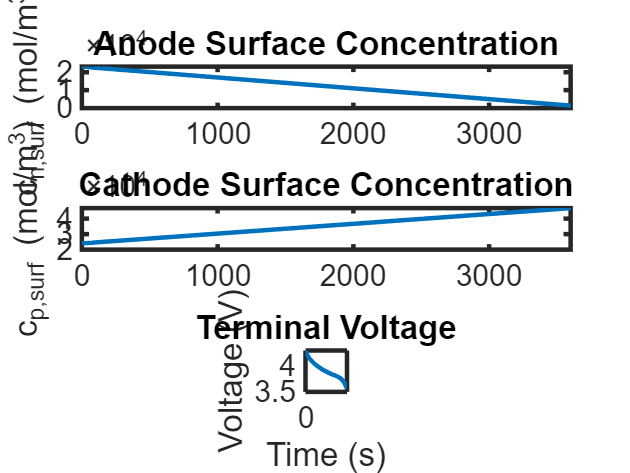

opts = odeset('RelTol',1e-6, 'AbsTol',1e-8);
[t_sol, x_sol] = ode15s(@(t,x) spm_ode_system(t, x, para), para.time_span, x0, opts);

% extract the ion concentrations in solid
% Do you want how to find the surface concentration?

c_n_all = x_sol(:, 1:para.Nr_anode+1);
c_p_all = x_sol(:, para.Nr_anode+2 : para.Nr_anode+1 + (para.Nr_cathode+1));

where the solution of the PDE is stored in  x_sol with time stamp t_sol. But it is convenient to extract the solid concentraions for post-processing later.

The voltage is obtained by post-processing the solution, 

V_cell = zeros(size(t_sol));
for k = 1:length(t_sol)
    V_cell(k) = compute_terminal_voltage(x_sol(k,:)', para);
end

where *compute_terminal_voltage*(x, para) is a function that takes in the states x and parameters. 

#### Task 2: write a function compute_terminal_voltage to compute voltage from the solid concentations (states) and parameters

Hint: the terminal voltage can be calculated by:


$$  V_{\text{cell}} = \Bigl[ U_{\text{cathode}}(\theta_c) + \eta_{\text{cathode}} \Bigr] - \Bigl[ U_{\text{anode}}(\theta_a) + \eta_{\text{anode}} \Bigr] - I\cdot R_{\text{int}},$$


where the term $I\cdot R_{\text{int}}$ represents the ohmic voltage drop within the cell due to current collectors. $\theta_c$ is the stoichometry of the surface concentration, i.e. $\theta_c=c_{s}^{\text{surf}}$/$c_{max}$ The overpotentials are computed using symmetric Butler-Volmer equation


$$ \eta = \frac{2RT}{F} \sinh^{-1}\!\left( \frac{I}{2\,i_0} \right),$$


where:

$R$ is the universal gas constant,

$F$ is the Faraday constant,

$i_0$ is the exchange current density calculated by $i_{0} = k_i(T) \, F \, \sqrt{c_e^{\text{avg}}} \, \sqrt{c_{s}^{\text{surf}}} \, \sqrt{c_{s}^{\text{max}} - c_{s}^{\text{surf}}},$ where $c_{s}^{\text{surf}}}$ is the surface concentration which can be obtained by 

Here is a template for the function in which you should complete "..."

function V_cell = compute_terminal_voltage(x, para)
    % Unpack 
    Nn = para.Nr_anode;
    Np = para.Nr_cathode;
   
    c_n_surf = x(Nn+1);           % anode surface concentration
    c_p_surf = x(Nn+1 + Np+1);    % cathode surface concentration
    
    % Compute surface stoichiometries
    x1 = c_n_surf / para.cs1_max;
    y3 = c_p_surf / para.cs3_max;
    
    % OCP
    U_n = para.U_ocp_anode(x1);
    U_p = para.U_ocp_cathode(y3);
    
    % Internal/contact resistance drop
    IR_drop = ... % voltage drop [V] = [A/m^2]*[Ω·m^2]
    
    % Overpotentials (very simplified or zero for demonstration)
    i_0_n = ...  % at anode
    i_0_p = ...  % at cathode
    eta_n = ...
    eta_p = ...
    % Terminal voltage
    V_cell = ...
end

## Part 5: Plotting the results

We can plot the surface concentration v.s. time and the voltage calculated from Task 2 for 1C charge and discharge. The code is provided below

% Example plot
lw = 3; % line width for the curves

figure(); 
subplot(3,1,1);
plot(t_sol, c_n_all(:,end), 'LineWidth',lw);
ylabel('c_{n,surf} (mol/m^3)');
xlim([0 3600]);
title('Anode Surface Concentration');
set(gca, 'FontSize', 20, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,2);
plot(t_sol, c_p_all(:,end), 'LineWidth',lw);
ylabel('c_{p,surf} (mol/m^3)');
xlim([0 3600]);
title('Cathode Surface Concentration');
set(gca, 'FontSize', 20, 'LineWidth', 3, 'Box', 'on');

subplot(3,1,3);
plot(t_sol, V_cell, 'LineWidth',lw);
xlabel('Time (s)'); ylabel('Voltage (V)');
title('Terminal Voltage');
axis square;
xlim([0 3600]);
set(gca, 'FontSize', 20, 'LineWidth', 3, 'Box', 'on');

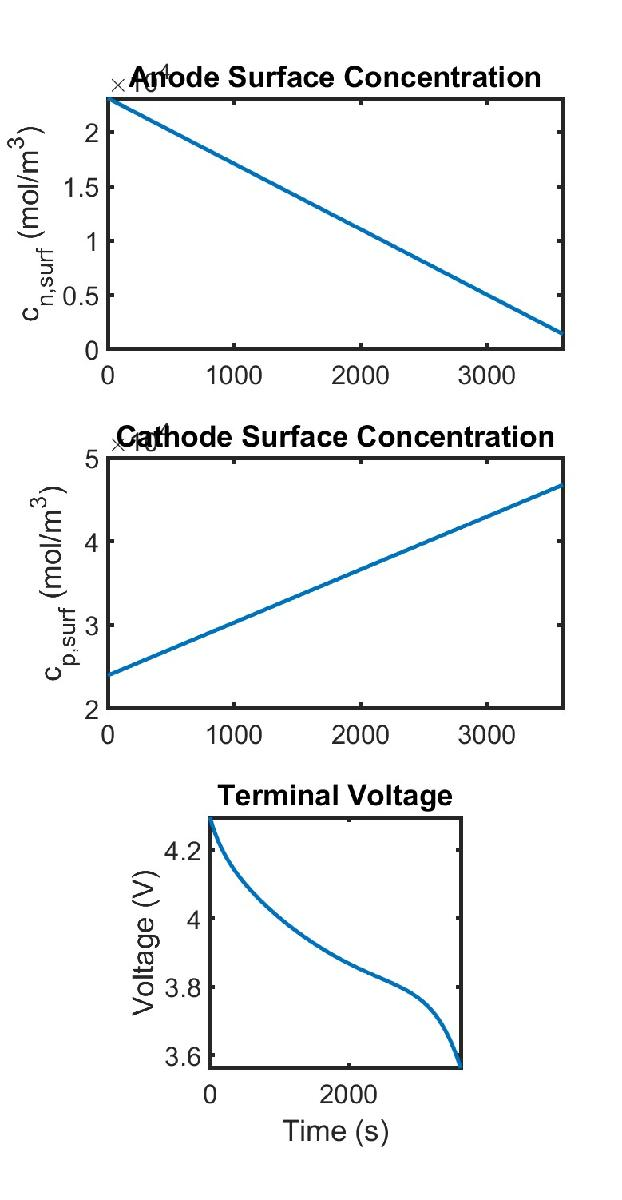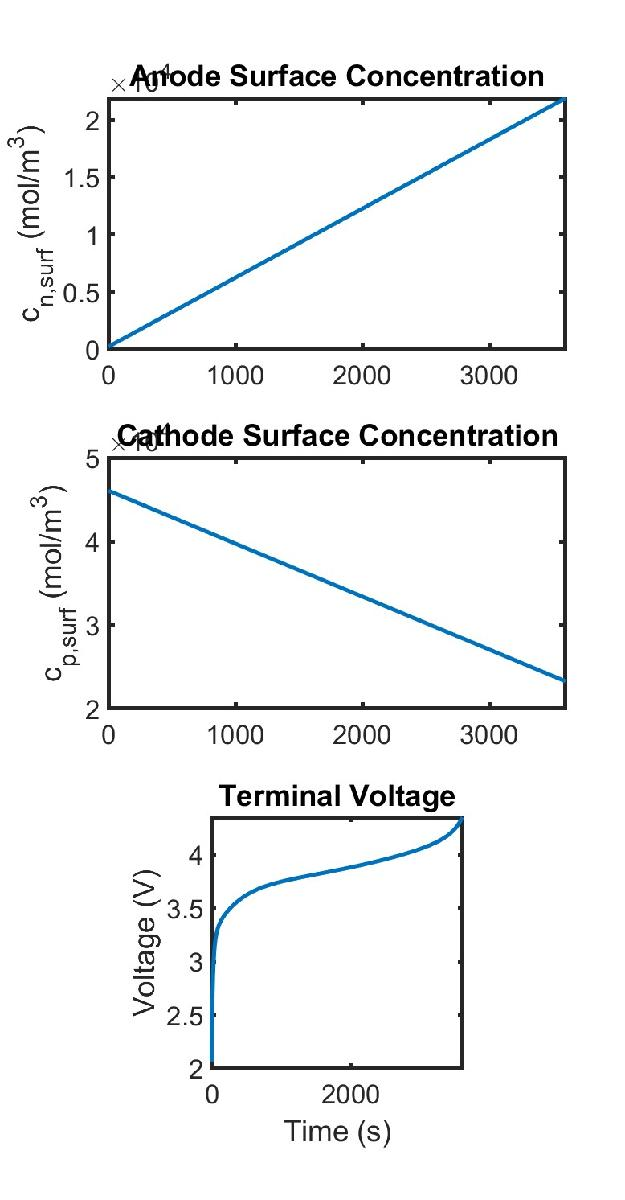

#### Task 3: With your voltage function, run a 2C simulation for charge and discharge